#  **3D image processing** **using mex-cuda-cublas Matrix Multiplication**

This example shows how to process two colour image using three dimensional Matrix Multiplication.

Read an image into the workspace, then convert the image to double.



[X,map] = imread('triangle.tiff');
if ~isempty(map)
    Im1 = ind2rgb(X,map);
end
[Y,map] = imread('triangle.tiff');
if ~isempty(map)
    Im2 = ind2rgb(Y,map);
end

Perform a three dimensional Matrix Multiplication  of the colour images using the `MM3D_CUBLAS `function..

K = MM3D_CUBLAS(single(Im1),single(Im2),0.0010);

Display the original colour image alongside the processed image.

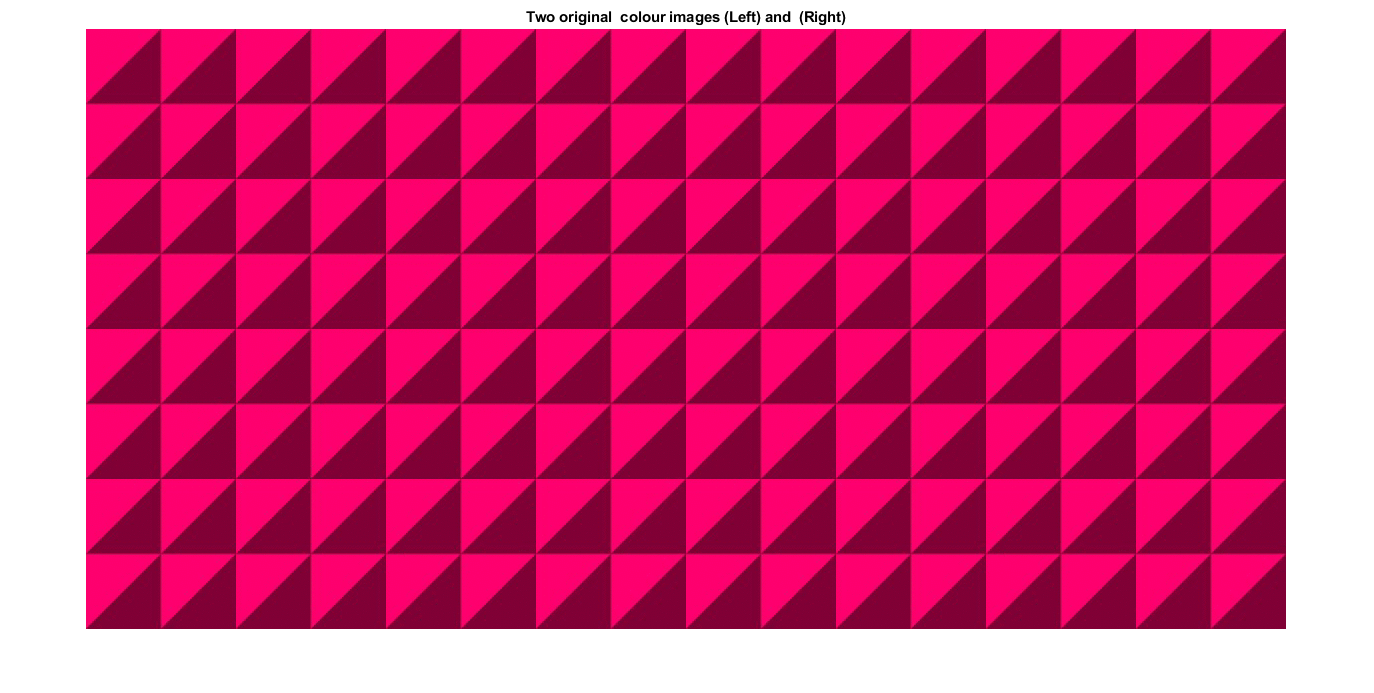

figure
imshowpair(Im1,Im2,'montage')
title('Two original  colour images (Left) and  (Right)');

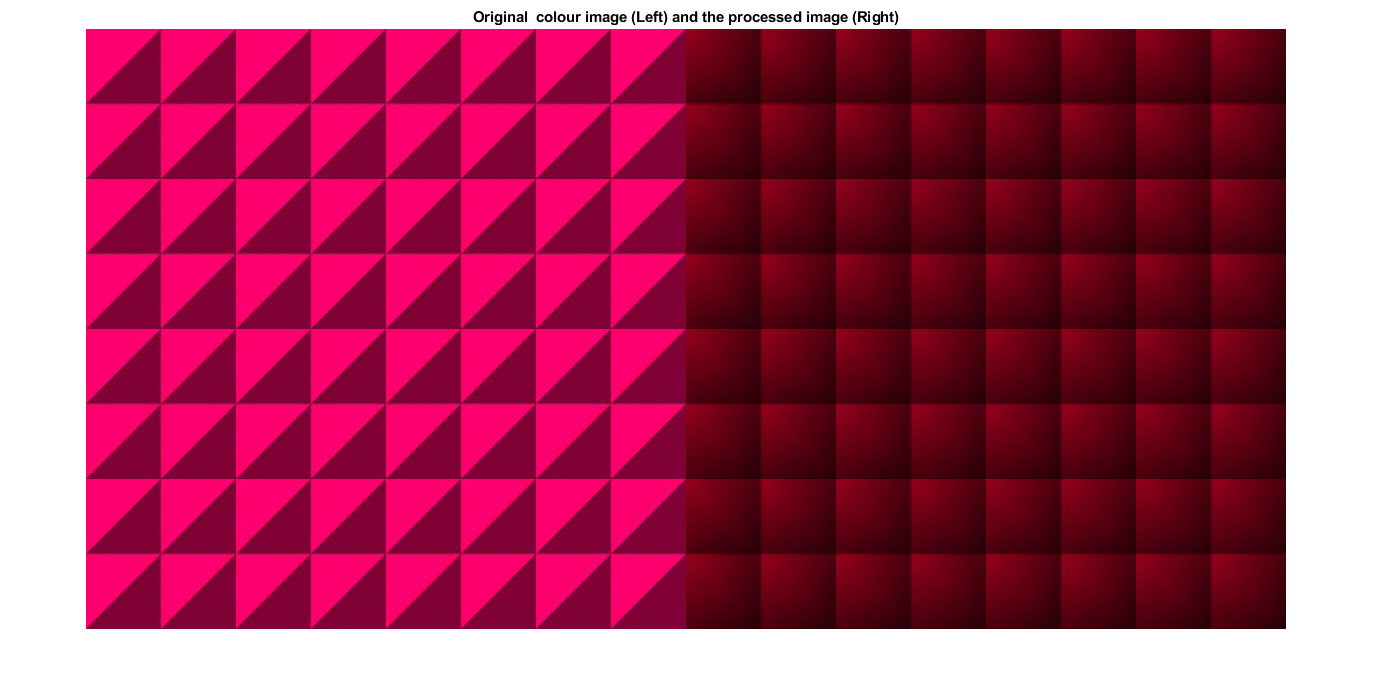


figure
imshowpair(Im1,K, 'montage')

title('Original  colour image (Left) and the processed image (Right)');